# Projeto dos sinais de excitacao para rodar na Planta de Pressão (Malha Aberta)

Os sinais gerados abaixo sao usados como referencia para o setpoint da posição,

na aquisicao, a referencia (projetada), a saida (posicao) a entrada (% enviada para a valvula) sao gravados.

clear
Ts = 1/1e2;    % Mudar para 250ms
zeropad = zeros(1,500);
valorDC = 50; % valor medio

## curva semi estatica

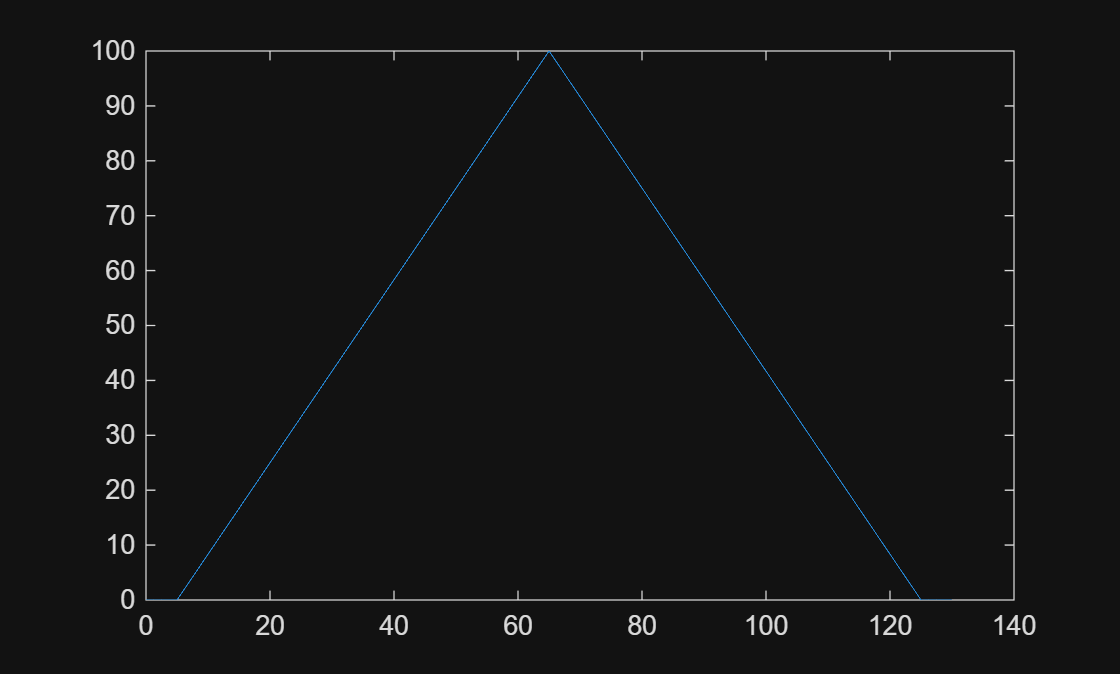


Tf = 60;
amp = 100;

t1 = 0:Ts:Tf;
N1= length(t1);
u1 = linspace(0,amp,N1);

u1 = [zeropad u1 u1(end:-1:1) zeropad];
N1 = length(u1);
t1 = ((1:N1)-1)*Ts;
plot(t1,u1)

## seq de degraus

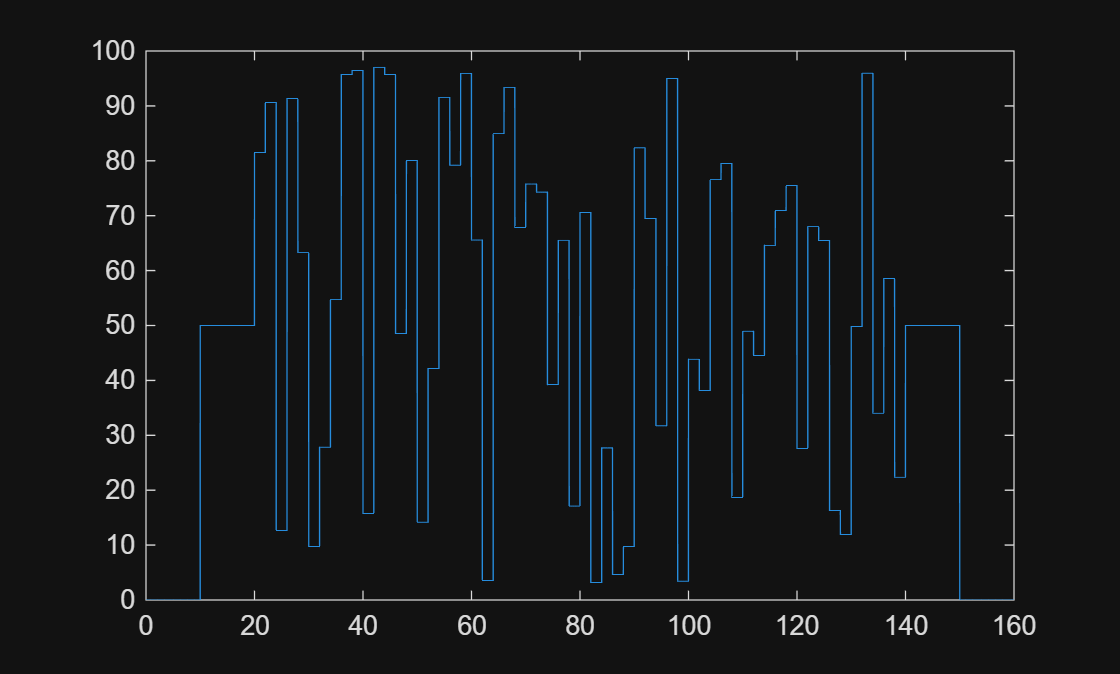

rng(0)
Tf = 120;
Tduracao = 2; % quantos seg de duracao cada degrau 
% Tduracao = 4; % quantos seg de duracao cada degrau 
% Tduracao = 6; % quantos seg de duracao cada degrau 

% amp = 15; 
amp = 50; 

t = (0:Ts:Tf);
N = length(t);
Ndeg = Tduracao/Ts; 
Nrand = (N-1)/Ndeg;
randSteps = amp*(2*rand(Nrand,1)-1);
Umat = repmat(randSteps,1,Ndeg)';

u2 = [zeropad zeropad ([zeropad zeropad Umat(:)' zeropad zeropad] + valorDC) zeropad zeropad];
N2 = length(u2);
t2 = ((1:N2)-1)*Ts;
plot(t2,u2)

## swept sine

% param
Fmax = 0.5; %raD
A = 50; % amplitude

T0 = 60; % period [s]
f0 = 1/T0; % frequency
k1 = 1; % [k1*f0,k2*f0] lowest and highest frequency respectively
k2 = Fmax/f0; % k2 > k1, natural numbers
disp(k1*f0) % freq inicial

    0.0167



disp(k2*f0) % freq final

    0.5000



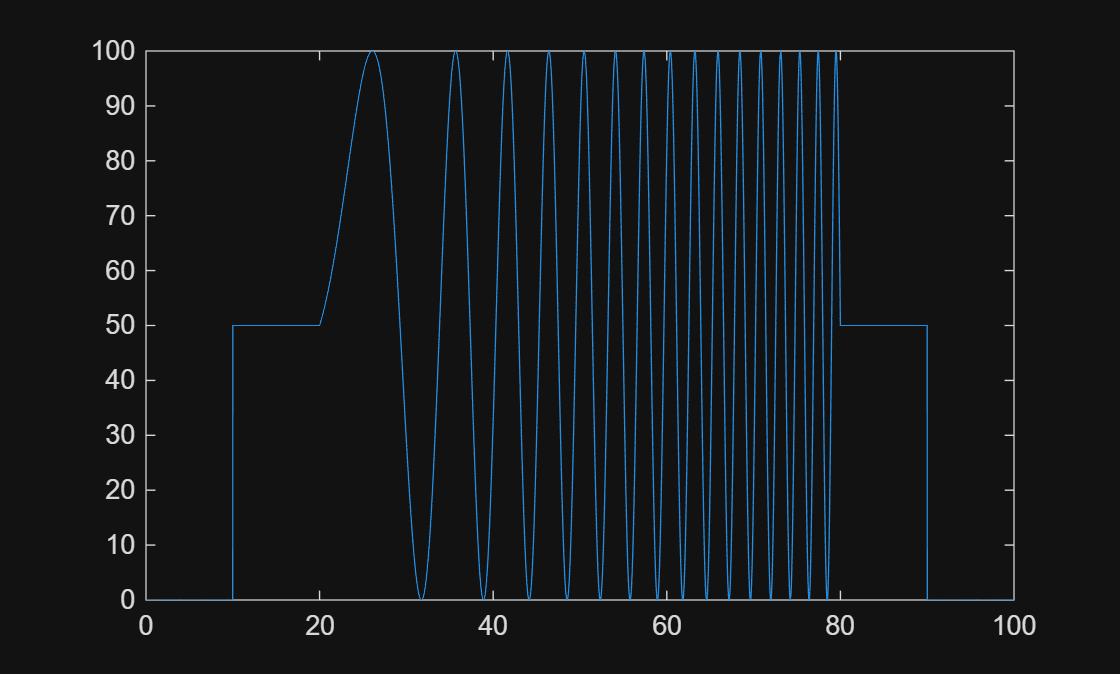

a = pi*(k2-k1)*f0^2;
b = 2*pi*k1*f0;

t3 = 0:Ts:T0;
% signal
u3 = A*sin((a*t3+b).*t3);

u3 = [zeropad zeropad ([zeropad zeropad u3 zeropad zeropad] + valorDC) zeropad zeropad];
N3 = length(u3);
t3 = ((1:N3)-1)*Ts;
% plots
figure,plot(t3,u3)

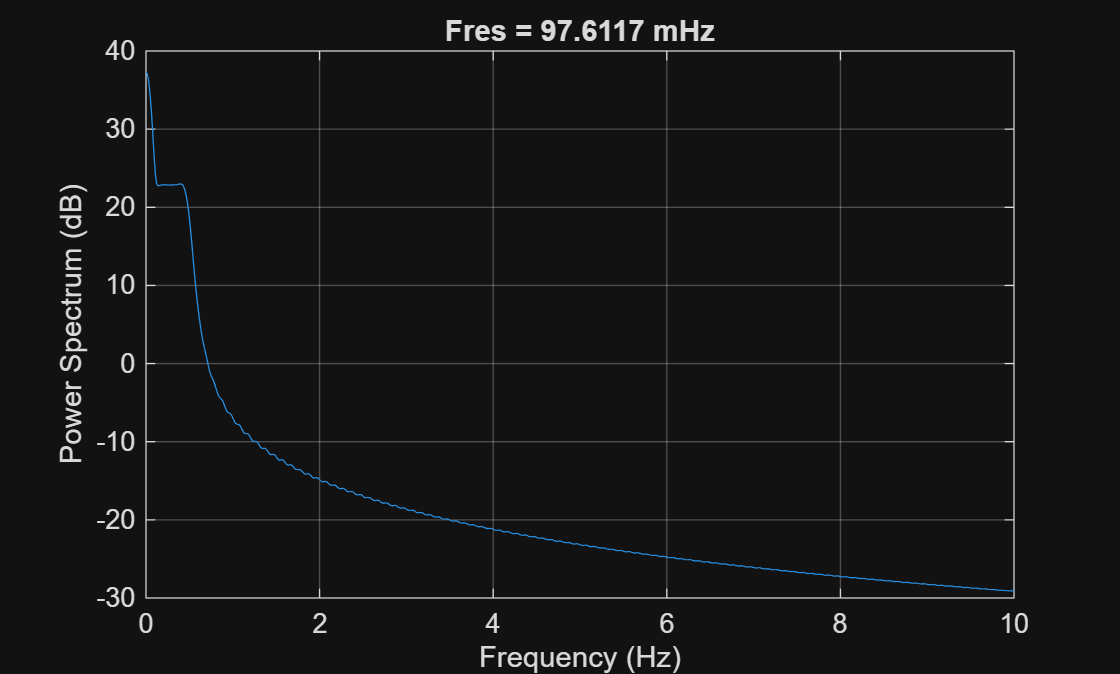

ut = timetable(u3','SampleRate',1/Ts);
figure,pspectrum(ut)
xlim([0 10])

## multi-seno (n realizacoes)

Fmax = 0.5;
% Amp = 15;
Amp = 50;
% Amp = 45;

% --------------- 1
rng(0)
[u, t] = multiSine(1/Ts, Fmax, Tf, Amp, 1);

multiSine is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\mathe\OneDrive - Grupo Marista\PUCPR\15 Semestre\CONTROLE AVANÇADO\Greybox\generate_ref_signal
    C:\Users\mathe\OneDrive - Grupo Marista\PUCPR\15 Semestre\CONTROLE AVANÇADO\GITs\1-4 DRONE - GIT\SYSTEM-IDENTIFICATION-AERO\MPC_Hardware_Test\generate_ref_signal

Change the MATLAB current folder or add its folder to the MATLAB path.


u4 = [zeropad zeropad ([zeropad zeropad u' zeropad zeropad] + valorDC) zeropad zeropad];
N4 = length(u4);
t4 = ((1:N4)-1)*Ts;

% plots
figure,plot(t4,u4)
ut = timetable(u4','SampleRate',1/Ts);
figure,pspectrum(ut)
xlim([0 10])